## Linear Regression - Kepler's 3rd Law (Solar System)

In this example we learn the basics of linear regression. We will take the semi-major axis and period information for several planets in our solar system and fit them in such a way that we can derive Kepler's 3rd Law.


$${\rm Period}^2 = {\rm Semi-major \ axis}^3$$


or


$$P^2 =a^3$$


First load in a dataset.

df = readtable('PHYS410_Solar_System.csv');

pl_name = transpose(df.Planet);
period_yr = transpose(df.Period_years);
semi_major_AU = transpose(df.Distance_AU);

If we adjust the powers in Kepler's 3rd Law and take the logarithm, we find...


$$P = a^{3/2}$$



$$\log_{10} P = (3/2) \log_{10} a
$$


which has the form


$$Y = m * X + b$$


Thus a linear fit of $\log_{10} P$ versus $\log_{10} a$ should give a slope m = 3/2 and b = 0 if ignoring experimental uncertainties.

Logarithm

log_period_yr = log10(period_yr);
log_semi_major_AU = log10(semi_major_AU);

## What is linear regression? 

There are many schools of thought on the nitty gritty of modeling regression - however it largely relates to suggesting random numbers to the coefficients of an equation we are trying to solve. The linear case is:


$$Y_{\rm prediction} = m_{\rm random} * X_{\rm actual} + b_{\rm random}
$$


It then tries to minimize a statistic, such as the residual of the actual values to the predicted values (or more commonly the square of it), in a relationship like this:


$$\Sigma^N_{i=1} (Y_{\rm actual,i} - Y_{\rm predicition,i})^2$$


In short it will try a random combination of m_random and b_random and measure the statistic, then keep trying until some minimum or convergence is reached. Let's try to visualize this:

n_rand = 100; % number of random points to consider
m_rand = 3*rand(n_rand)-1.5; % rand(n) gives n random numbers uniformly distributed between 0,1
b_rand = rand(n_rand) - 0.5; % gives random number between -0.5 and 0.5

m_best = 0;
b_best = 0;
resid = 10000;
for i=1:n_rand
    for j=1:n_rand
        y_test = m_rand(i)*log_semi_major_AU + b_rand(j);
        resid_test = sum((y_test - log_period_yr).^2);
        if resid_test < resid
            resid = resid_test;
            m_best = m_rand(i);
            b_best = b_rand(j);
            disp("New min residual ="+string(resid))
        end
    end
end

New min residual =0.50813
New min residual =0.37584
New min residual =0.37459
New min residual =0.36936
New min residual =0.02486
New min residual =0.0081537
New min residual =0.00719
New min residual =0.0069948
New min residual =0.0013267
New min residual =0.0012636



disp("m approx " + string(m_best))

m approx 1.4706


disp("b approx " + string(b_best))

b approx 0.010018


Luckily - MATLAB has built in functions for this process and can do a better job converging to an answer.

## Try linear regression using the function "polyfit" - which takes the arguments, polyfit(xarray, yarray, degree of polynomial)

p = polyfit(log_semi_major_AU,log_period_yr,1);

disp("m_best="+string(p(1))+" and b_best="+string(p(2)))

m_best=1.4997 and b_best=0.00012582


We can take these coefficients and create a predicted array of periods to overplot out actual data.

## Create a line.

max_log_semi_major_AU = max(log_semi_major_AU); % biggest log a
min_log_semi_major_AU = min(log_semi_major_AU); % smallest log a

dummy_log_semi_major_AU = linspace(min_log_semi_major_AU,max_log_semi_major_AU,100); % make an array of log a values that are uniformly spaced
pred_log_period_yr = p(2)+p(1)*dummy_log_semi_major_AU; % prediction

## Now create a graph!

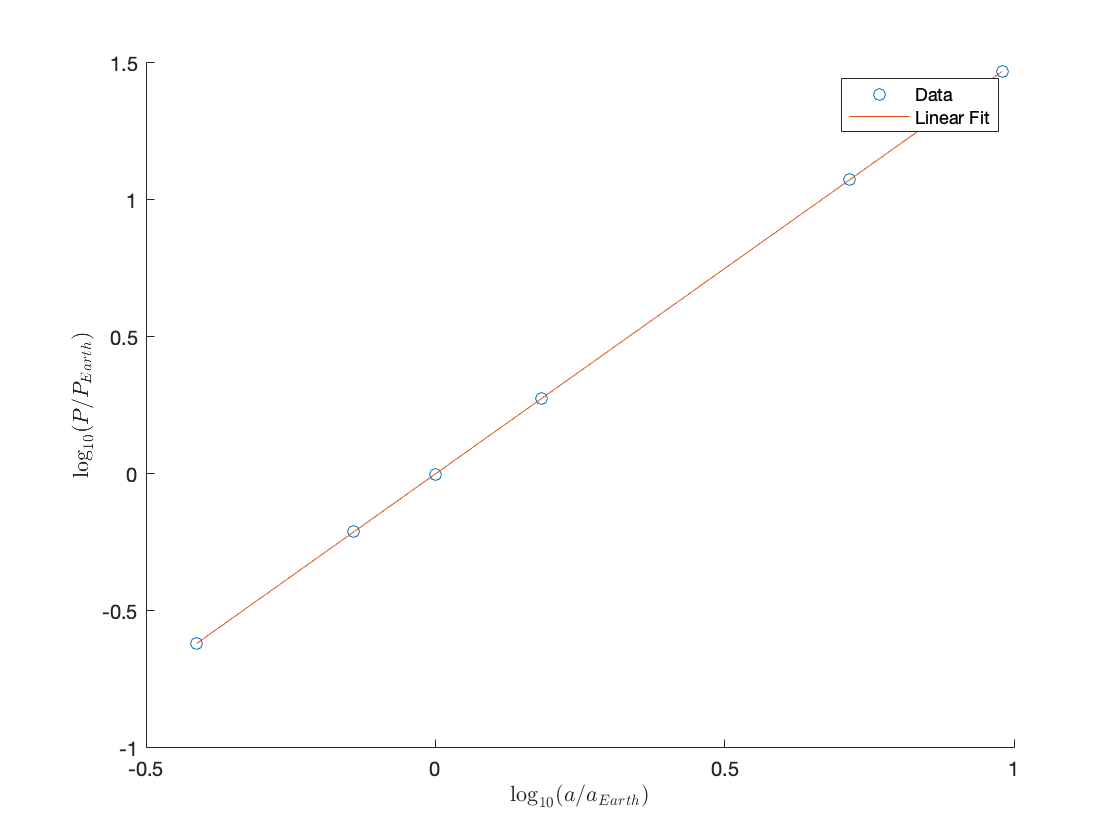

scatter(log_semi_major_AU,log_period_yr)
xlabel("$\log_{10} (a / a_{Earth}) $",'Interpreter','latex')
ylabel("$\log_{10} (P / P_{Earth}) $",'Interpreter','latex')

hold on

plot(dummy_log_semi_major_AU,pred_log_period_yr)
hold off

legend("Data","Linear Fit")